# Appendix: MATLAB Scripts

## Questions

Question 1

clear
dryMass = 1200; % kg
deltaV = 1.45*1000; % m/s     NOT km
Isp_mono = 229; % s
Isp_bi = 323; % s
g = 9.81; % m/s^2

%   Find amount of propellant needed
wetMass_mono = dryMass*exp(deltaV / (Isp_mono*g));
wetMass_bi = dryMass*exp(deltaV / (Isp_bi*g));

propMass_mono = wetMass_mono-dryMass;
propMass_bi = wetMass_bi-dryMass;

fprintf('Monoprop propellant mass = %f\nBiprop propellant mass = %f.',propMass_mono,propMass_bi)

Monoprop propellant mass = 1088.216986
Biprop propellant mass = 696.353013.

## Workout Problems:

Problem 1

clear
rLEO = 550+6378; % km
rGEO = 36000+6378; % km
TGEO = 24*3600; % s
mu = 398600.435; % km^3/s^2 for Earth
Isp = 323;
dryMass = 350; % kg
g = 9.81; % m/s^2

%   Find deltaV 1 (LEO to transfer)
vLEO = sqrt(mu/rLEO);
    aXfer = (rLEO+rGEO)/2;
    eqn1 = (2/rLEO) - (1/aXfer);
vXfer1 = sqrt(mu*eqn1);
deltaV1 = abs(vXfer1-vLEO);

%   Find deltaV 2 (transfer to GEO)
vGEO = sqrt(mu/rGEO);
    aXfer = (rLEO+rGEO)/2;
    eqn2 = (2/rGEO) - (1/aXfer);
vXfer2 = sqrt(mu*eqn2);
deltaV2 = abs(vGEO-vXfer2);

%   Find total DV (LEO to transfer to GEO)
deltaV = deltaV1 + deltaV2;

%   Find propellant weight
deltaV_meters = deltaV*1000;
wetMass = dryMass*exp(deltaV_meters / (Isp*g));
propMass = wetMass-dryMass;
fprintf('Total DV = %f km/s\nRequires %f kg of propellant',deltaV,propMass)

Total DV = 3.800824 km/s
Requires 811.479390 kg of propellant

Problem 2

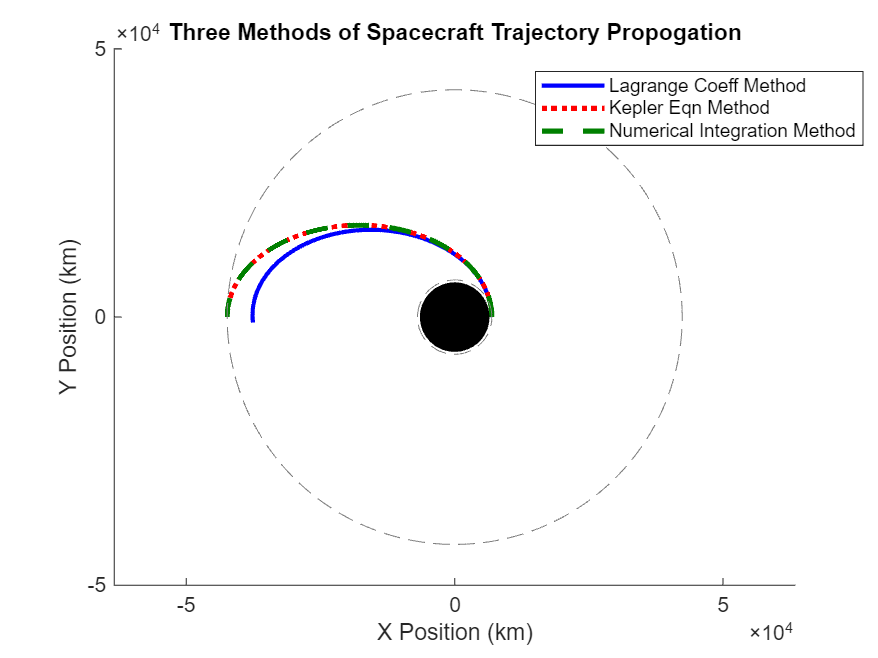

%   Lagrange Coeff Method
TXfer = 2*pi*sqrt(aXfer^3/mu); % s
dt = round(TXfer/200); % matches better when /600

q0 = [rLEO;0;0;0;vXfer1;0];
q(:,1)=q0;

for i = 1:90 % use 300 when using /600 in dt
    f(i) = 1 - ( mu*dt^2 / (2*norm(q(1:3,i))^3) ) + (mu*dt^3 / (2*norm(q(1:3,i))^5 )) * dot(q(1:3,i),q(4:6,i));
    g(i) = dt - (mu*dt^3 / (6*norm(q(1:3,i))^3) );
    f_dot(i) = -mu*dt/(norm(q(1:3,i))^3) + (3*mu*dt^2/(2*norm(q(1:3,i))^5)) * dot(q(1:3,i),q(4:6,i));
    g_dot(i) = 1 - mu*dt^2/(2*norm(q(1:3,i))^3);

    q(1:3,i+1) = f(i).*q(1:3,i) + g(i).*q(4:6,i);
    q(4:6,i+1) = f_dot(i).*q(1:3,i) + g_dot(i).*q(4:6,i);
end

lagrange_x = q(1,:);
lagrange_y = q(2,:);

% ------------------------------------------------------------------------

%   Kepler's Eqn Method
eXfer = (rGEO-rLEO)/(rGEO+rLEO);
[E,theta,M] = AngleCalculator(aXfer,eXfer);
r_theta=(aXfer.*(1-eXfer.^2))./(1+(eXfer.*cos(theta)));

endIndex_kepler = round(length(r_theta)/2); % To only plot the first half of the Xfer orbit
kepler_x = r_theta.*cos(theta);
kepler_x = kepler_x(1:endIndex_kepler);
kepler_y = r_theta.*sin(theta);
kepler_y = kepler_y(1:endIndex_kepler);

% ------------------------------------------------------------------------

%   Numerical Integration Method
clear q q0
q0 = [rLEO;0;0;0;vXfer1;0];
options = odeset('RelTol',1e-10,'AbsTol',1e-12);
tspan = 0:10:round(TXfer);
global a_SRP_Magnitude
a_SRP_Magnitude = 0;
global a_Drag_Value
a_Drag_Value = 0;
[t, Q]=ode45(@integrator,tspan,q0,options);

endIndex = round(length(Q)/2); % To only plot the first half of the Xfer orbit
ode_x=Q(:,1);
ode_x = ode_x(1:endIndex);
ode_y=Q(1:endIndex,2);
ode_y = ode_y(1:endIndex);

% ------------------------------------------------------------------------

%   Plotting
ang = 0:1:360; % deg
earth_x = 6378*cosd(ang);
earth_y = 6378*sind(ang);
LEO_x = rLEO*cosd(ang);
LEO_y = rLEO*sind(ang);
GEO_x = rGEO*cosd(ang);
GEO_y = rGEO*sind(ang);

figure
hold on
plot(lagrange_x,lagrange_y,'Color','b','LineWidth',2)
plot(kepler_x,kepler_y,'LineStyle',':','LineWidth',2.5,'Color','r')
plot(ode_x,ode_y,'LineWidth',2.5,'LineStyle','--','Color','#008000')
plot(LEO_x,LEO_y,'LineStyle','--','Color','#808080')
plot(GEO_x,GEO_y,'LineStyle','--','Color','#808080')
fill(earth_x,earth_y,'k')
hold off
xlabel('X Position (km)')
ylabel('Y Position (km)')
legend(["Lagrange Coeff Method", "Kepler Eqn Method", "Numerical Integration Method"], "Position",  [0.6099 0.7794 0.3732, 0.1119])
title('Three Methods of Spacecraft Trajectory Propogation')
xlim([-50000 50000])
ylim([-50000 50000])
xticks([-50000 0 50000])
yticks([-50000 0 50000])
axis equal

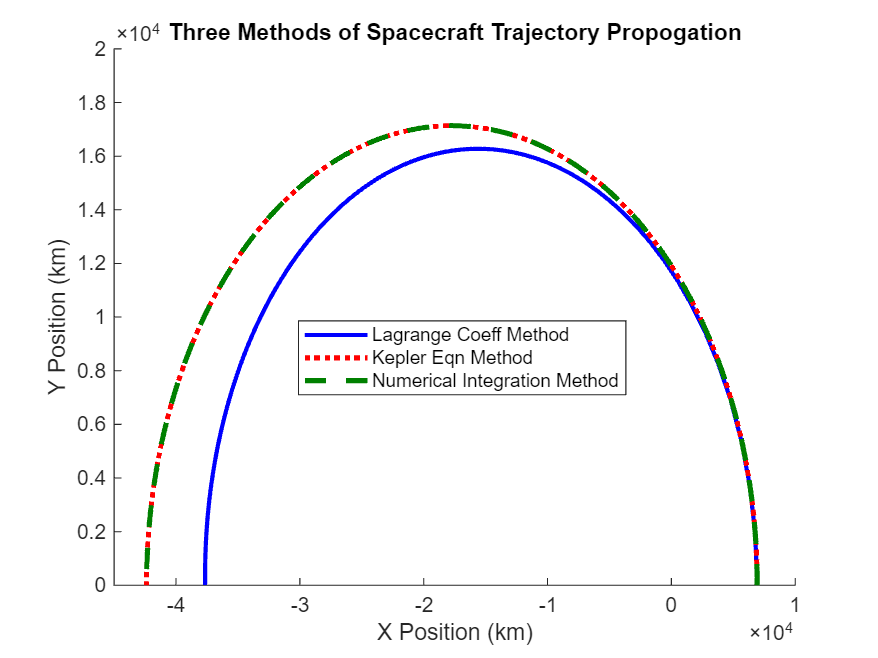

figure
hold on
plot(lagrange_x,lagrange_y,'Color','b','LineWidth',2)
plot(kepler_x,kepler_y,'LineStyle',':','LineWidth',2.5,'Color','r')
plot(ode_x,ode_y,'LineWidth',2.5,'LineStyle','--','Color','#008000')
hold off
xlabel('X Position (km)')
ylabel('Y Position (km)')
legend(["Lagrange Coeff Method", "Kepler Eqn Method", "Numerical Integration Method"], "Position", [0.3393 0.3997 0.3732, 0.1119])
title('Three Methods of Spacecraft Trajectory Propogation')
xlim([-45000 10000])
ylim([0 20000])

Problem 3

Part a - LEO w/ mass = 200 kg

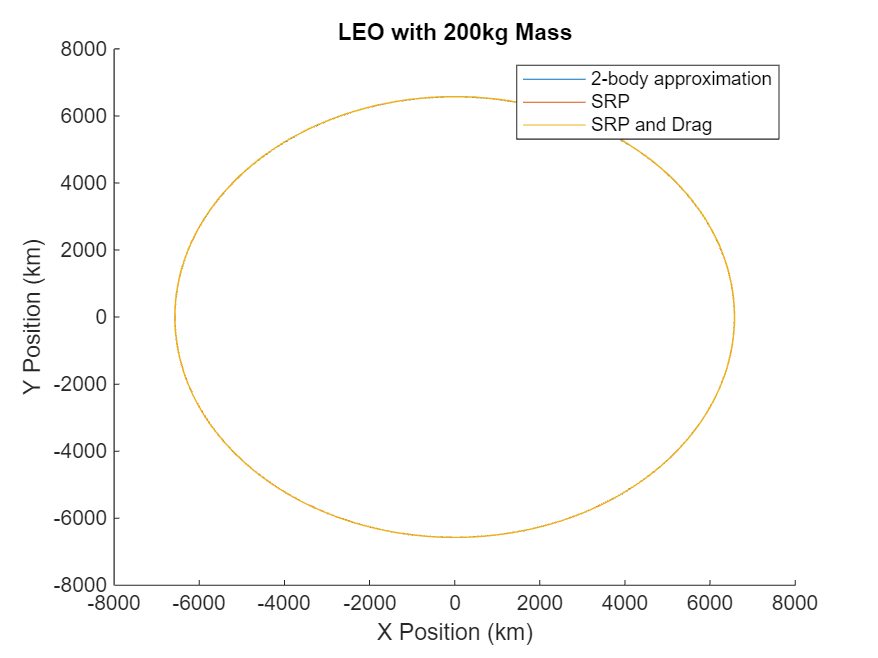

clear
mass = 200; % kg
solarPanelArea = 3*10^(-6); % km^2
solarPressure_1AU = 4.56*10^(-6)*10^(6); % N/km^2

rho = 10^(-12)*10^(9); % kg/km^3;
mu = 398600.435; % km^3/s^2 - for Earth
a = 200+6378; % km
Cdrag = 0.5;
Area = 3*10^(-6); % km^2

T = 2*pi*sqrt(a^3/mu); % s
dt = 100;
tspan = 0:dt:10*T; % s
vp = sqrt(mu/a); % km/s - for Circular orbit
q0 = [0;-a;0;vp;0;0];

% ------------------------------------------------------------------------

%   2-body and SRP perturbation
[Q_2body,Q_srp] = KeplerSRP(tspan,q0,solarPanelArea,solarPressure_1AU,mass);

x_2body = Q_2body(:,1);
y_2body = Q_2body(:,2);

x_srp = Q_srp(:,1);
y_srp = Q_srp(:,2);

% ------------------------------------------------------------------------

%   Solar pressure and atmospheric drag perturbations
global a_SRP_Magnitude
a_SRP_Magnitude = solarPanelArea*solarPressure_1AU/mass; % km/s^2
global a_Drag_Value
a_Drag_Value = 0.5*rho*Area*Cdrag;

options = odeset('RelTol',1e-10,'AbsTol',1e-12);
[t_iii, Q_iii]=ode45(@integrator,tspan,q0,options);
x_iii = Q_iii(:,1);
y_iii = Q_iii(:,2);

% ------------------------------------------------------------------------

figure
hold on
plot(x_2body,y_2body)
plot(x_srp,y_srp)
plot(x_iii,y_iii)
hold off
xlabel('X Position (km)')
ylabel('Y Position (km)')
legend('2-body approximation','SRP','SRP and Drag')
title('LEO with 200kg Mass')

Problem 3

Part a - LEO w/ mass = 600 kg

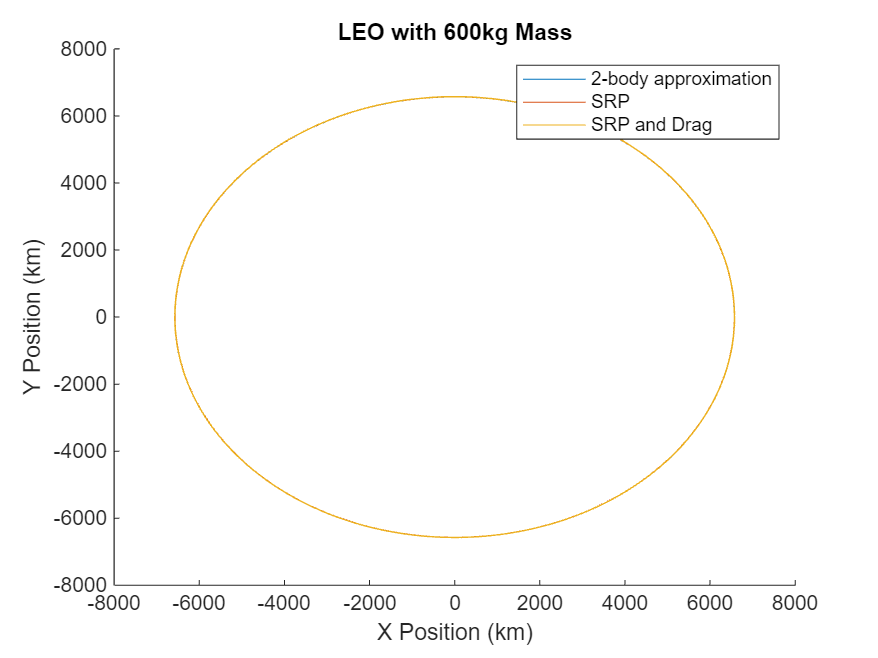

clear
a = 200+6378; % km
mass = 600; % kg

solarPanelArea = 3*10^(-6); % km^2
solarPressure_1AU = 4.56*10^(-6)*10^(6); % N/km^2

rho = 10^(-12)*10^(9); % kg/km^3;
mu = 398600.435; % km^3/s^2 - for Earth
Cdrag = 0.5;
Area = 3*10^(-6); % km^2

T = 2*pi*sqrt(a^3/mu); % s
dt = 100;
tspan = 0:dt:10*T; % s
vp = sqrt(mu/a); % km/s - for Circular orbit
q0 = [0;-a;0;vp;0;0];

% ------------------------------------------------------------------------

%   2-body and SRP perturbation
[Q_2body,Q_srp] = KeplerSRP(tspan,q0,solarPanelArea,solarPressure_1AU,mass);

x_2body = Q_2body(:,1);
y_2body = Q_2body(:,2);

x_srp = Q_srp(:,1);
y_srp = Q_srp(:,2);

% ------------------------------------------------------------------------

%   Solar pressure and atmospheric drag perturbations
global a_SRP_Magnitude
a_SRP_Magnitude = solarPanelArea*solarPressure_1AU/mass; % km/s^2
global a_Drag_Value
a_Drag_Value = 0.5*rho*Area*Cdrag;

options = odeset('RelTol',1e-10,'AbsTol',1e-12);
[t_iii, Q_iii]=ode45(@integrator,tspan,q0,options);
x_iii = Q_iii(:,1);
y_iii = Q_iii(:,2);

% ------------------------------------------------------------------------

figure
hold on
plot(x_2body,y_2body)
plot(x_srp,y_srp)
plot(x_iii,y_iii)
hold off
xlabel('X Position (km)')
ylabel('Y Position (km)')
legend('2-body approximation','SRP','SRP and Drag')
title('LEO with 600kg Mass')

Problem 3

Part b - MEO w/ mass = 200 kg

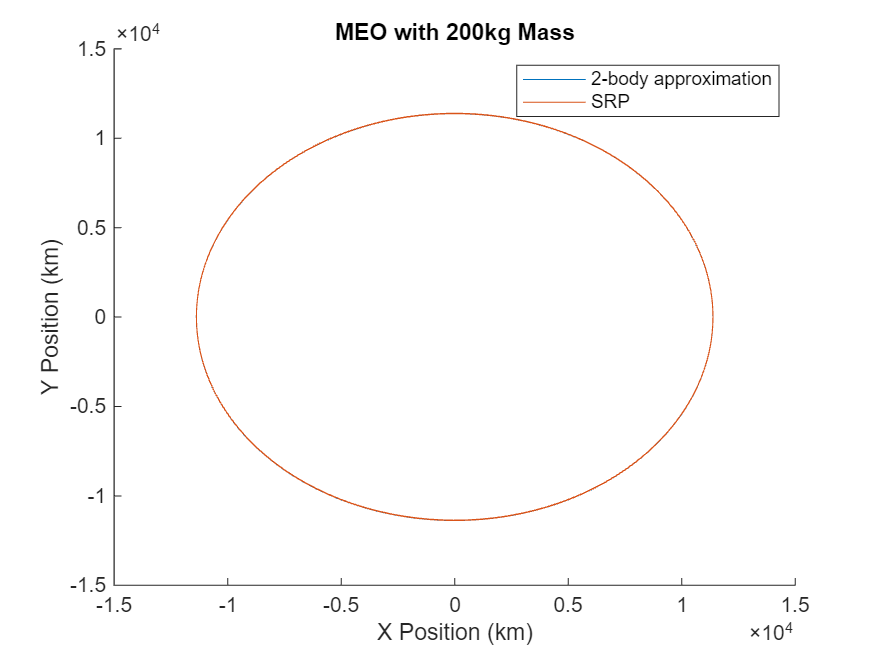

clear
a = 5000 + 6378; % km
mass = 200; % kg

solarPanelArea = 3*10^(-6); % km^2
solarPressure_1AU = 4.56*10^(-6)*10^(6); % N/km^2

rho = 10^(-12)*10^(9); % kg/km^3;
mu = 398600.435; % km^3/s^2 - for Earth
Cdrag = 0.5;
Area = 3*10^(-6); % km^2

T = 2*pi*sqrt(a^3/mu); % s
dt = 100;
tspan = 0:dt:10*T; % s
vp = sqrt(mu/a); % km/s - for Circular orbit
q0 = [0;-a;0;vp;0;0];

% ------------------------------------------------------------------------

[Q_2body,Q_srp] = KeplerSRP(tspan,q0,solarPanelArea,solarPressure_1AU,mass);

x_2body = Q_2body(:,1);
y_2body = Q_2body(:,2);

x_srp = Q_srp(:,1);
y_srp = Q_srp(:,2);

% ------------------------------------------------------------------------

figure
hold on
plot(x_2body,y_2body)
plot(x_srp,y_srp)
hold off
xlabel('X Position (km)')
ylabel('Y Position (km)')
legend('2-body approximation','SRP')
title('MEO with 200kg Mass')

Problem 3

Part b - MEO w/ mass = 600 kg

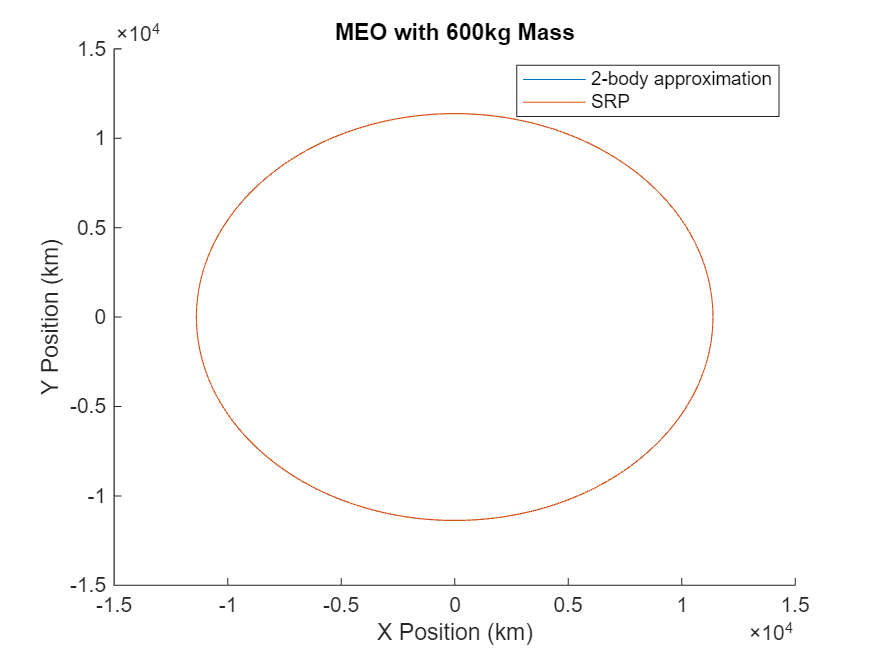

clear
a = 5000 + 6378; % km
mass = 600; % kg

solarPanelArea = 3*10^(-6); % km^2
solarPressure_1AU = 4.56*10^(-6)*10^(6); % N/km^2

rho = 10^(-12)*10^(9); % kg/km^3;
mu = 398600.435; % km^3/s^2 - for Earth
Cdrag = 0.5;
Area = 3*10^(-6); % km^2

T = 2*pi*sqrt(a^3/mu); % s
dt = 100;
tspan = 0:dt:10*T; % s
vp = sqrt(mu/a); % km/s - for Circular orbit
q0 = [0;-a;0;vp;0;0];

% ------------------------------------------------------------------------

[Q_2body,Q_srp] = KeplerSRP(tspan,q0,solarPanelArea,solarPressure_1AU,mass);

x_2body = Q_2body(:,1);
y_2body = Q_2body(:,2);

x_srp = Q_srp(:,1);
y_srp = Q_srp(:,2);

% ------------------------------------------------------------------------

figure
hold on
plot(x_2body,y_2body)
plot(x_srp,y_srp)
hold off
xlabel('X Position (km)')
ylabel('Y Position (km)')
legend('2-body approximation','SRP')
title('MEO with 600kg Mass')

Problem 3

Part c - GEO w/ mass = 200 kg

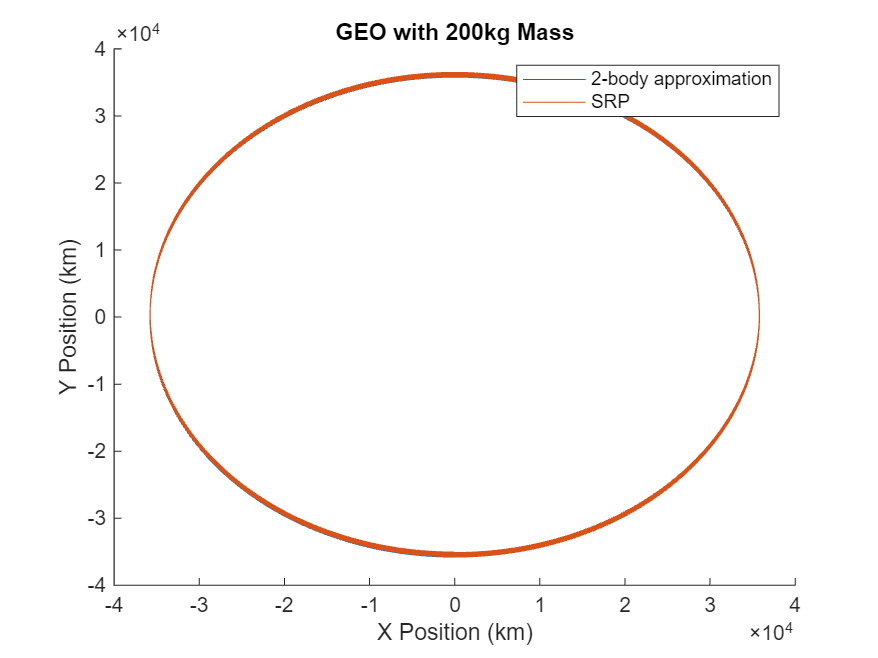

clear
a = 35786; % km
mass = 200; % kg

solarPanelArea = 3*10^(-6); % km^2
solarPressure_1AU = 4.56*10^(-6)*10^(6); % N/km^2

rho = 10^(-12)*10^(9); % kg/km^3;
mu = 398600.435; % km^3/s^2 - for Earth
Cdrag = 0.5;
Area = 3*10^(-6); % km^2

T = 2*pi*sqrt(a^3/mu); % s
dt = 100;
tspan = 0:dt:10*T; % s
vp = sqrt(mu/a); % km/s - for Circular orbit
q0 = [0;-a;0;vp;0;0];

% ------------------------------------------------------------------------

[Q_2body,Q_srp] = KeplerSRP(tspan,q0,solarPanelArea,solarPressure_1AU,mass);

x_2body = Q_2body(:,1);
y_2body = Q_2body(:,2);

x_srp = Q_srp(:,1);
y_srp = Q_srp(:,2);

% ------------------------------------------------------------------------

figure
hold on
plot(x_2body,y_2body)
plot(x_srp,y_srp)
hold off
xlabel('X Position (km)')
ylabel('Y Position (km)')
legend('2-body approximation','SRP')
title('GEO with 200kg Mass')

Problem 3

Part c - GEO w/ mass = 600 kg

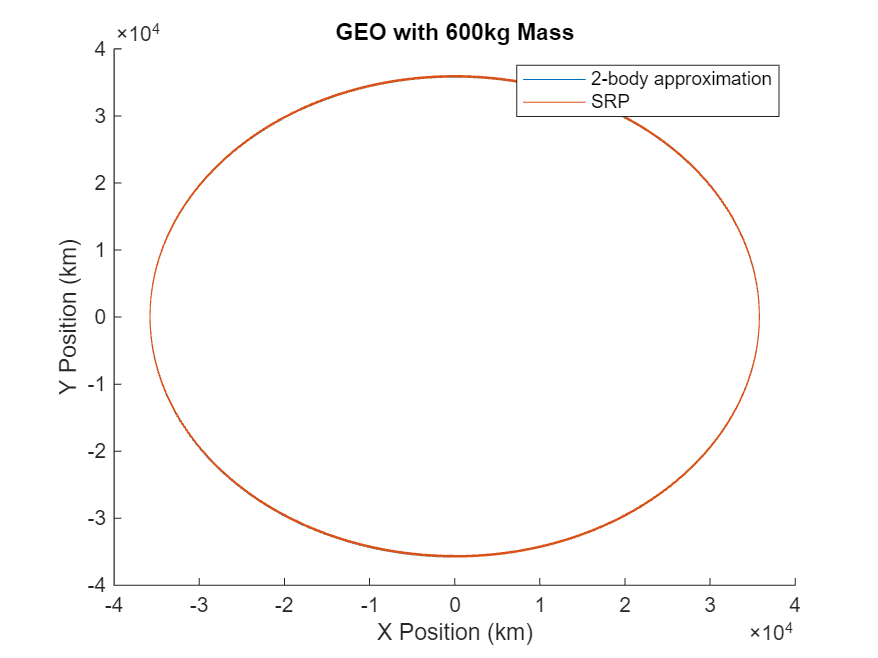

clear
a = 35786; % km
mass = 600; % kg

solarPanelArea = 3*10^(-6); % km^2
solarPressure_1AU = 4.56*10^(-6)*10^(6); % N/km^2

rho = 10^(-12)*10^(9); % kg/km^3;
mu = 398600.435; % km^3/s^2 - for Earth
Cdrag = 0.5;
Area = 3*10^(-6); % km^2

T = 2*pi*sqrt(a^3/mu); % s
dt = 100;
tspan = 0:dt:10*T; % s
vp = sqrt(mu/a); % km/s - for Circular orbit
q0 = [0;-a;0;vp;0;0];

% ------------------------------------------------------------------------

[Q_2body,Q_srp] = KeplerSRP(tspan,q0,solarPanelArea,solarPressure_1AU,mass);

x_2body = Q_2body(:,1);
y_2body = Q_2body(:,2);

x_srp = Q_srp(:,1);
y_srp = Q_srp(:,2);

% ------------------------------------------------------------------------

figure
hold on
plot(x_2body,y_2body)
plot(x_srp,y_srp)
hold off
xlabel('X Position (km)')
ylabel('Y Position (km)')
legend('2-body approximation','SRP')
title('GEO with 600kg Mass')

Problem 4

Part a - un-perturbed orbital elements

clear
mu = 398600.435; % for Earth
%   In Geocentric (XYZ) Coordinates:
r0 = [7000;250;-50]; % km
v0 = [0.1;8.25;0.05]; % km/s
r = norm(r0);
v = norm(v0);

denom = (2/r) - (v^2/mu);
aInit = 1/denom;

h = cross(r0,v0);
e_vector = (1/mu).* ( cross(v0,h) - (mu/r).*r0 );
eInit = norm(e_vector);

iInit = acosd(h(3)/norm(h)); % degrees

N = [-h(2);h(1);0];
if N(2)>= 0
    RAANInit = acosd(N(1)/norm(N)); % degrees
else
    RAANInit = 360 - acosd(N(1)/norm(N)); % degrees
end


Ne = dot(N,e_vector);
if e_vector(3) >= 0
    omegaInit = acosd(Ne/(norm(N)*eInit)); % degrees
else
    omegaInit = 360 - acosd(Ne/(norm(N)*eInit)); % degrees
end

fprintf('Un-perturbed orbital elements: \na = %f km \ne = %f \ni = %f deg \nomega = %f deg \nOMEGA = %f deg',aInit,eInit,iInit,omegaInit,RAANInit)

Un-perturbed orbital elements: 
a = 8715.363470 km 
e = 0.201796 
i = 0.549625 deg 
omega = 295.489434 deg 
OMEGA = 50.128191 deg

Problem 4

Part b - Propogation over 50 orbital periods w/ SRP

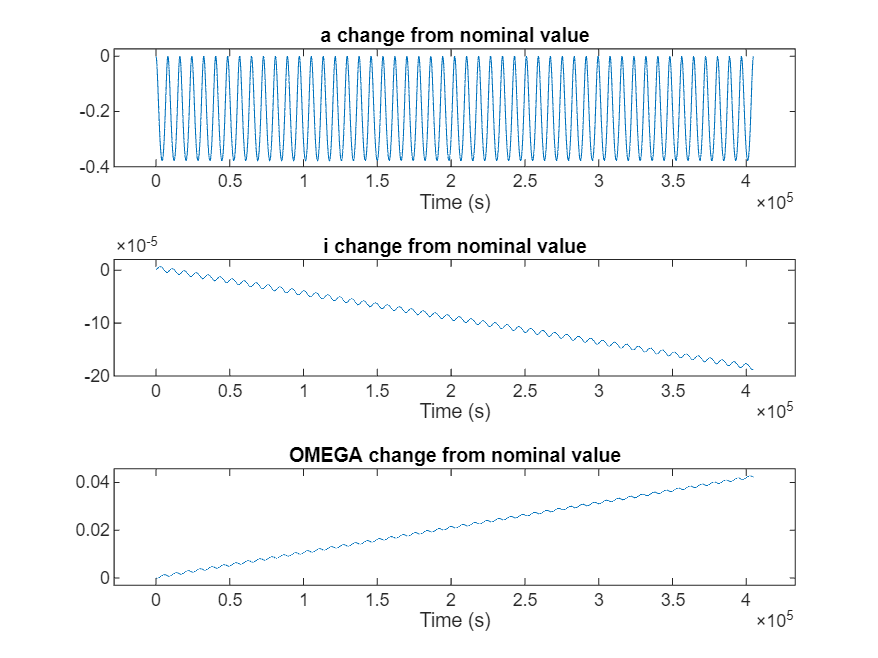

mass = 400; % kg
solarPanelArea = 5*10^(-6); % km^2
solarPressure_1AU = 4.56*10^(-6)*10^(6); % N/km^2

T = 2*pi*sqrt(aInit^3/mu); % s
dt = 100; % s
tspan = 0:dt:50*T;
q0 = [r0;v0];

[~,Q] = KeplerSRP(tspan,q0,solarPanelArea,solarPressure_1AU,mass);
rArray = Q(:,1:3)';
vArray = Q(:,4:6)';

[a,e,i,omega,RAAN] = OrbitalElements(rArray,vArray);
aChange = a - aInit;
eChange = e - eInit;
iChange = i - iInit;
omegaChange = omega - omegaInit;
RAANChange = RAAN - RAANInit;

figure
tiledlayout(3,1)
nexttile
plot(tspan,aChange)
title('a change from nominal value')
xlabel('Time (s)')
axis padded
nexttile
plot(tspan,iChange)
xlabel('Time (s)')
title('i change from nominal value')
axis padded
nexttile
plot(tspan,RAANChange)
xlabel('Time (s)')
title('OMEGA change from nominal value')
axis padded

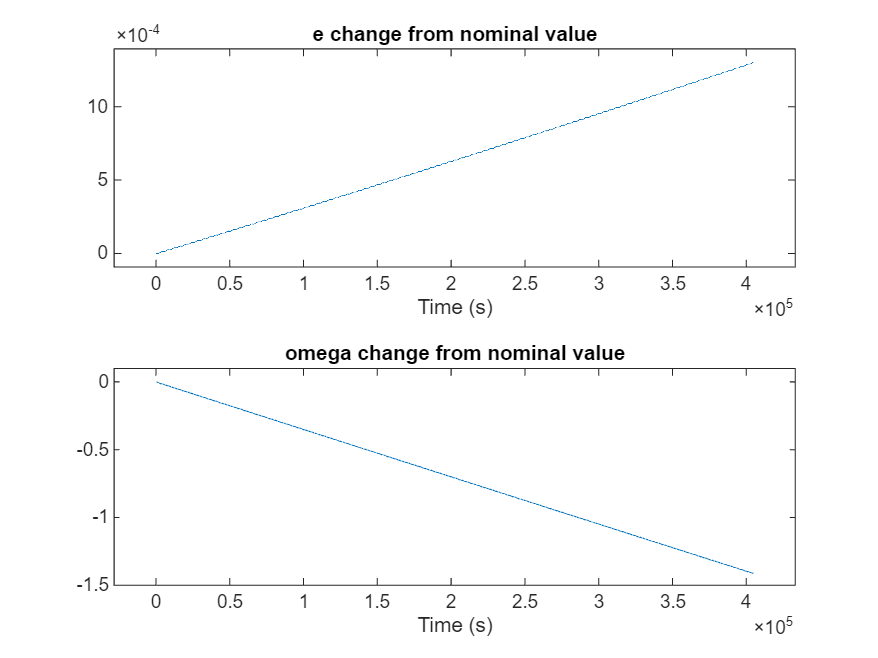


figure
tiledlayout(2,1)
nexttile
plot(tspan,eChange)
xlabel('Time (s)')
title('e change from nominal value')
axis padded
nexttile
plot(tspan,omegaChange)
xlabel('Time (s)')
title('omega change from nominal value')
axis padded

function [EArray, thetaArray, MArray] = AngleCalculator(a,e)

    tolerance = 0.0001; 
    mu = 398600.435; % for Earth
    period = 2*pi*sqrt(a^3/mu); % seconds

    for t = 1:round(period)
        % Calculate Mean anomaly
        MArray(t) = sqrt(mu/(a^3))*t;
    
        % Newton's Method to Calculate Eccentric anomaly
        E(1) = MArray(t);
        f = @(E) E-e.*sin(E)-MArray(t);
        fprime = @(E) 1-e.*cos(E);
        
        for i=1:10
            E(i+1) = E(i) - (f(E(i))/fprime(E(i)));
            error(i) = abs(E(i)-E(i+1));
            if error(i)<tolerance
                break
            end
        end
        numIterations = i;
        EArray(t) = E(i);

        % Calculate True anomaly
        root = sqrt( (1+e)/(1-e) );
        thetaArray(t) = 2*atan(root*tan(EArray(t)/2));

    end

end

% ------------------------------------------------------------------------

function [Q_2body,Q_srp] = KeplerSRP(tspan,q0,solarPanelArea,solarPressure_1AU,mass)
    
    %   No perturbations (2-body approximation)
    global a_Drag_Value
    global a_SRP_Magnitude
    a_Drag_Value = 0;
    a_SRP_Magnitude = 0;
    
    options = odeset('RelTol',1e-10,'AbsTol',1e-12);
    [t_2body, Q_2body]=ode45(@integrator,tspan,q0,options);
    
    
    %   Only solar pressure perturbation
    a_SRP_Magnitude = solarPanelArea*solarPressure_1AU/mass; % km/s^2
    a_Drag_Value = 0;
    
    [t_srp, Q_srp]=ode45(@integrator,tspan,q0,options);

end

% ------------------------------------------------------------------------

function qdot =  integrator(t,q)

    mu = 398600.435; % for Earth
    global a_Drag_Value
    global a_SRP_Magnitude
    
    r = sqrt(q(1)^2+q(2)^2+q(3)^2);
    v = sqrt(q(4)^2+q(5)^2+q(6)^2);

    ux = q(4)/v;
    uy = q(5)/v;
    uz = q(6)/v;
    
    qdot(1)=q(4);
    qdot(2)=q(5);
    qdot(3)=q(6);
    
    qdot(4)=-(mu/r^3)*q(1) + a_SRP_Magnitude + a_Drag_Value*v^2.*ux;
    qdot(5)=-(mu/r^3)*q(2) + a_Drag_Value*v^2.*uy;
    qdot(6)=-(mu/r^3)*q(3) + a_Drag_Value*v^2.*uz;
          
    qdot=qdot';

end

% ------------------------------------------------------------------------

function [a,e,inclination,omega,RAAN] = OrbitalElements(rArray,vArray)
    
    mu = 398600.435; % for Earth

    for i = 1:length(rArray(1,:))
        r(i) = norm(rArray(:,i));
        v(i) = norm(vArray(:,i));

        % denom(i) = (2/r(i)) - (v(i)^2/mu);
        % a(i) = 1/denom(i);
        a(i) = -mu/ (v(i)^2 - (2*mu/r(i)));
        
        h(:,i) = cross(rArray(:,i),vArray(:,i));
        e_vector(:,i) = (1/mu).* ( cross(vArray(:,i),h(:,i)) - (mu/r(i)).*rArray(:,i) );
        e(i) = norm(e_vector(:,i));
        
        inclination(i) = acosd(h(3,i)/norm(h(:,i))); % degrees
        
        N(:,i) = cross([0;0;1],h(:,i));
        if N(2,i)>= 0
            RAAN(i) = acosd(N(1,i)/norm(N(:,i))); % degrees
        else
            RAAN(i) = 360 - acosd(N(1,i)/norm(N(:,i))); % degrees
        end
        
        
        Ne(i) = dot(N(:,i),e_vector(:,i));
        if e_vector(3,i) >= 0
            omega(i) = acosd(Ne(i)/(norm(N(:,i))*e(:,i))); % degrees
        else
            omega(i) = 360 - acosd(Ne(i)/(norm(N(:,i))*e(:,i))); % degrees
        end
    
    end

end
